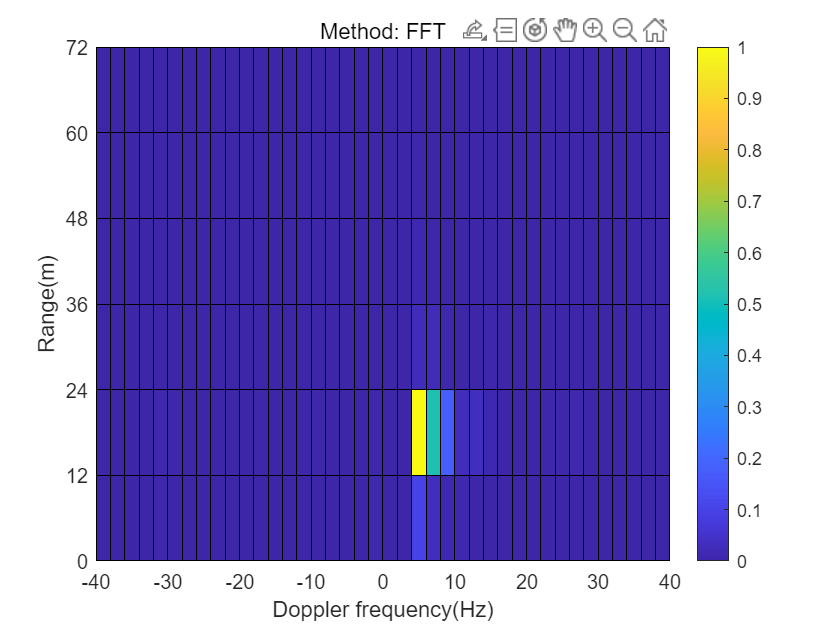

tau = 4.0000e-08

fd = 4

load("data_1.mat");
xr=seq_ref;
xs=seq_sur;figure
tic
[tau,fd]=corEsti(xs,xr,'plot','Method: FFT')

toc

历时 9.899303 秒。


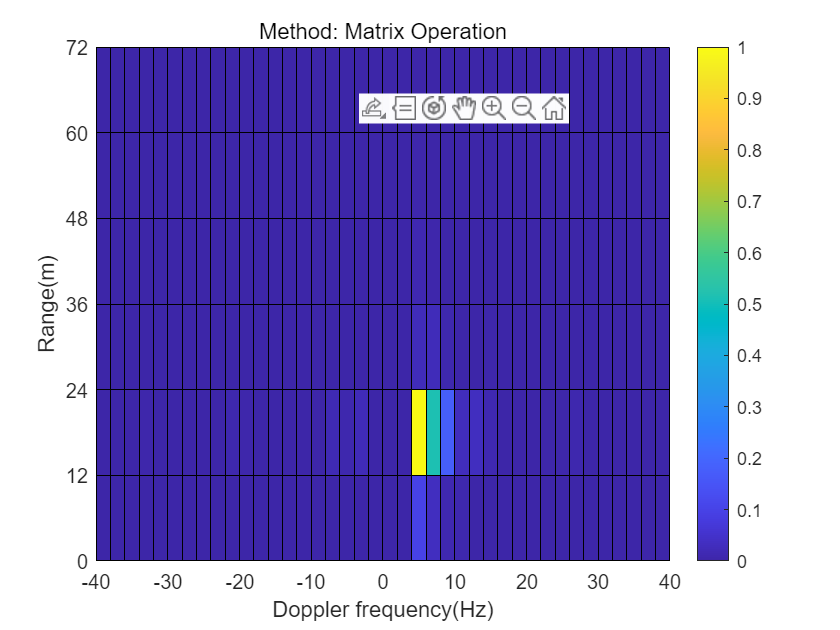

tau = 4.0000e-08

fd = 4

tic
[tau,fd]=corEsti(xs,xr,'plot','Method: Matrix Operation')

toc

历时 66.813195 秒。


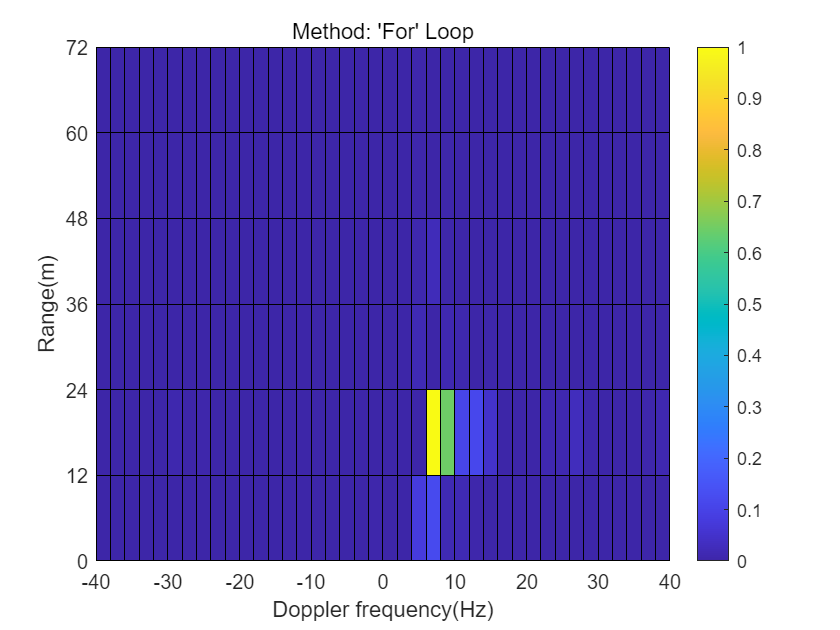

tau = 4.0000e-08

fd = 6

tic
[tau,fd]=corEsti(xs,xr,'plot','Method: ''For'' Loop')

toc

历时 627.714547 秒。


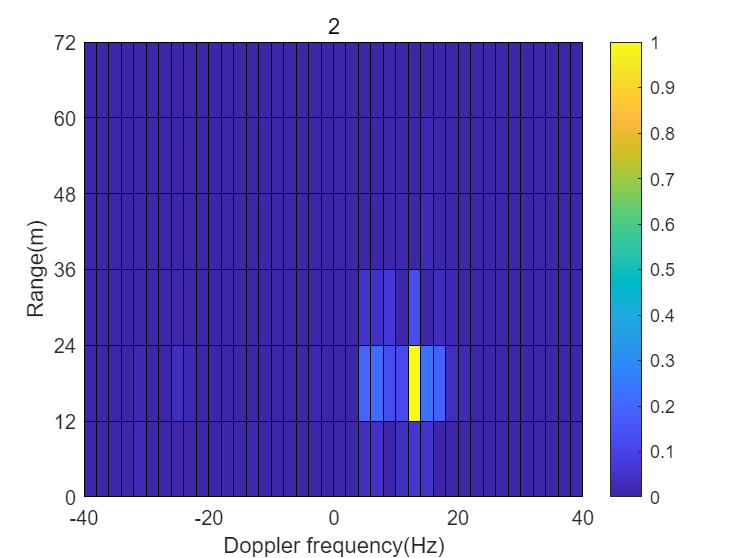

tau = 4.0000e-08

fd = 12

load("data_2.mat");
xr=seq_ref;
xs=seq_sur;figure
tic
[tau,fd]=corEsti(xs,xr,'plot','2')

toc

历时 11.824309 秒。


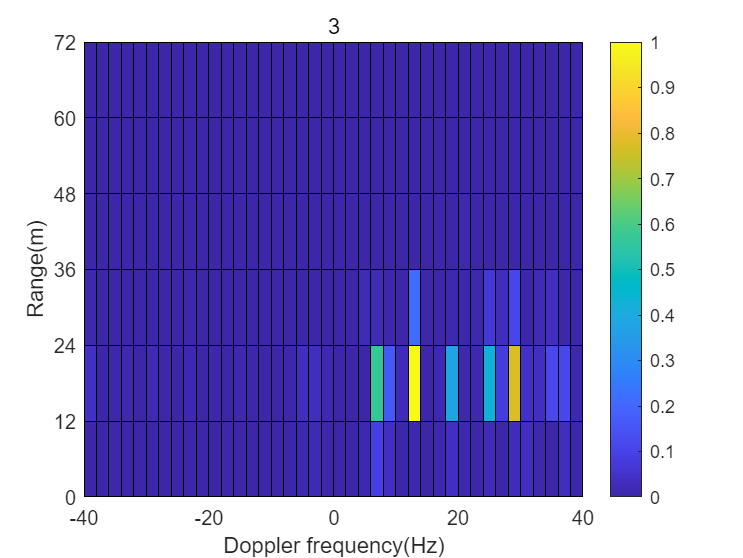

tau = 4.0000e-08

fd = 12

load("data_3.mat");
xr=seq_ref;
xs=seq_sur;figure
tic
[tau,fd]=corEsti(xs,xr,'plot','3')

toc

历时 11.957135 秒。


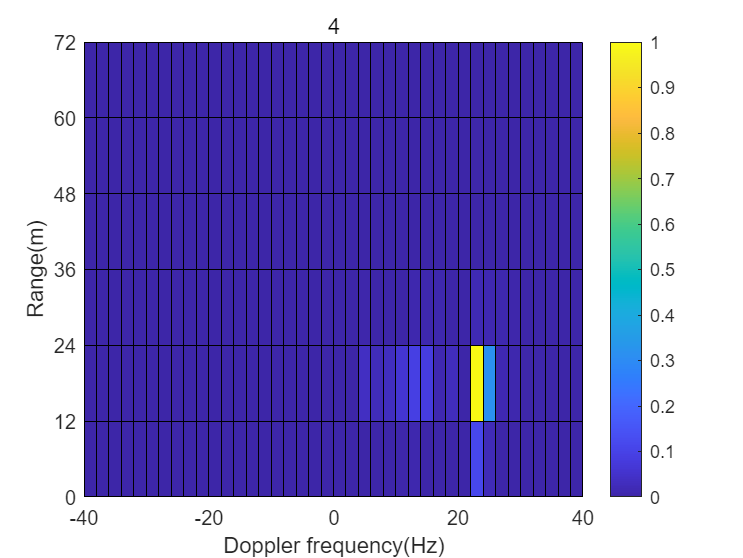

tau = 4.0000e-08

fd = 22

load("data_4.mat");
xr=seq_ref;
xs=seq_sur;figure
tic
[tau,fd]=corEsti(xs,xr,'plot','4')

toc

历时 14.594734 秒。


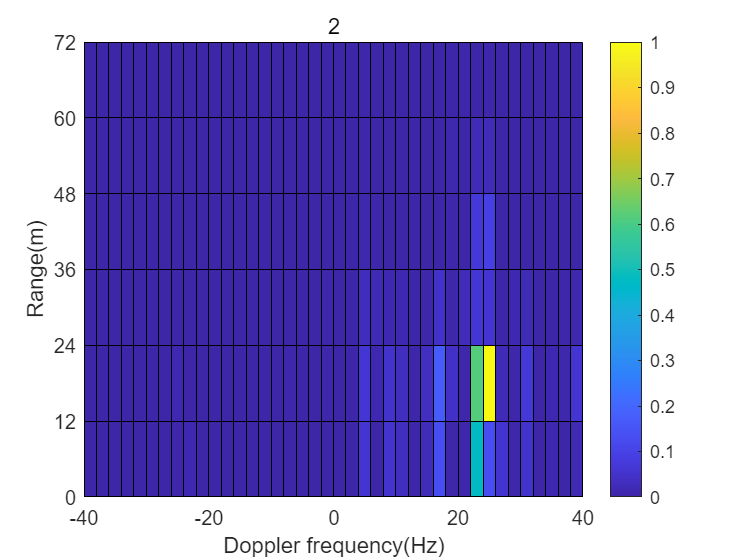

tau = 4.0000e-08

fd = 24

load("data_5.mat");
xr=seq_ref;
xs=seq_sur;figure
tic
[tau,fd]=corEsti(xs,xr,'plot','5')

toc

历时 14.127206 秒。


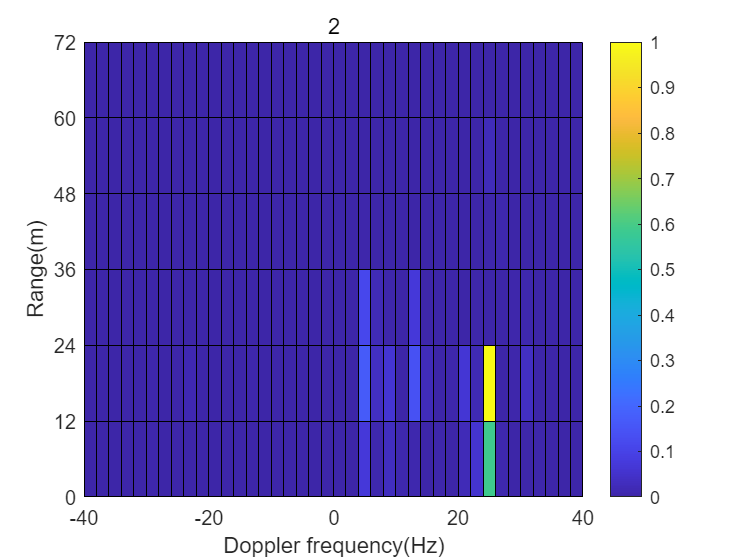

tau = 4.0000e-08

fd = 24

load("data_6.mat");
xr=seq_ref;
xs=seq_sur;figure
tic
[tau,fd]=corEsti(xs,xr,'plot','6')

toc

历时 13.719423 秒。


function [tau,fd]=corEsti(y_surv,y_ref,varargin)
    
    %可选参数: 是否作图?'plot','save'
    fs=25000000;
    corMat=zeros(7,41);
    Tau=linspace(0,1/fs*6,7);
    Fd=linspace(-40,40,41);


    for i=1:7
        zero_compensation=zeros(1,fix(Tau(i)*fs));%时延后补长信号以对齐
        ys=[y_surv,zero_compensation];
        yr=[zero_compensation,y_ref];
        %fft
        Y=fft(ys.*conj(yr));
        corMat(i,:)=fftshift(abs(Y(fix(Fd.*length(ys)/fs)+21)));

        %dot
        % for j=1:41
        %     corMat(i,j)=abs(sum(ys.*conj(yr).*exp_component(length(ys),Fd(j),fs)));
        % end
        
        %for
        for j=1:41
            for k=1:length(ys)
                corMat(i,j)=corMat(i,j)+ys(k).*conj(yr(k)).*exp(-2j*pi*Fd(j)*k/fs);
            end
            corMat(i,j)=abs(corMat(i,j));
        end
    end
    [~,I]=max(corMat(:));%寻找corMat中最大值索引
    [m,n]=ind2sub(size(corMat),I);%索引转为横纵索引

    tau=Tau(m);
    fd=Fd(n);
    
    %是否作图
    numVar=nargin-2;
    
    if isempty(varargin)
        return
    elseif strcmp(varargin{1},'plot')||strcmp(varargin{1},'save')
        if numVar<2
            disp('No enough arguments. Check title and/or filename.')
            return
        end
        h=figure;

        minVal = min(corMat(:));
        maxVal = max(corMat(:));

        % 进行 0-1 标准化,3次方加强效果
        corMat=((corMat - minVal) / (maxVal - minVal)).^3;
        
        pcolor(Fd,Tau.*3e8,corMat);colorbar
        
        xlabel("Doppler frequency(Hz)"),ylabel("Range(m)"),yticks(0:12:72)
        title(varargin{2})

        if strcmp(varargin{1},'save')
            if numVar<3
                disp('Filename not detected!')
                return
            end
            saveas(h,varargin{3},'png')
        end
    else 
        disp('Wrong input.')
    end
end

function y=exp_component(n,fd,fs)%dot法要调用的函数
    y=exp((-2i*pi*fd/fs).*linspace(0,n-1,n));
end